# JANUS Matlab Code Demos

**Author**: Michel Barbeau

**Version**: September 5th, 2022

## Initialization

Set the path to the directory containing the JANUS Matlab code: "janus-m-3.0.5"".

cd '/Users/freezzzy/Desktop/things to work on/Research/Oceanus 2/SECURITY-LAYER-JANUS-CU'
%cd '/Users/michelbarbeau/Dropbox/MyLiveScripts/JANUS-CU'

## 1. Simple Transmitter Example

This shows calling the full tranmitter implemention generating the broadband signal.

It reads parameters from the file 'parameter_sets.csv', which is a spreadsheet. The 2nd parameter selects the set of parameters with #Id 1. In this example:

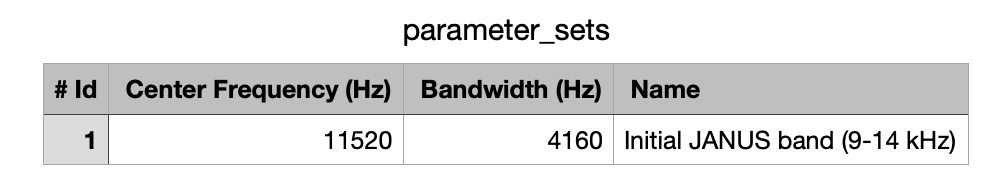

The carrier frequency is 11,520 Hz.

The output is written to file "janus.wav", in the current directory.

% Load application data, in hex (only rightmost 34 bits are used)
% params.packet_app_data = '3FFFF';
% params.stream_driver_args = 'test_janus.wav'
% Generate packet and broadband signal
% [pkt,state,params,signal] = simple_tx('parameter_sets.csv',1,params);
% disp(pkt);
[tx_pkt, tx_state,params,signal] = simple_tx('parameter_sets.csv', 1, ...
    'stream_driver_args', 'test_janus.wav',...
    'packet_class_id', 17,... % Venilia
    'packet_app_type', 0, 'packet_reserv_time', 100, ...
    'packet_app_data', '3FFFF') % rightmost 34 bits only are used

tx_pkt = struct with fields:
            bytes: [1 182 52 9 227 182 61 98]
          version: 3
         mobility: 0
         schedule: 1
            tx_rx: 1
          forward: 0
         class_id: 17
    class_id_name: 'OPEN'
         app_type: 0
    reserv_repeat: 0
      reserv_time: 107.9157
       cargo_size: 0
         app_data: 262143
              crc: 50
     crc_validity: 1
            cargo: ''


tx_state = struct with fields:
          pset_id: 1
        pset_name: 'Initial JANUS band (9-14 kHz)'
            cfreq: 11520
           bwidth: 3840
         chip_frq: 160
         chip_dur: 0.0063
           prim_q: 13
           prim_a: 2
           nblock: 12
    coded_symbols: [224×1 double]


params = struct with fields:
    stream_driver_args: 'test_janus.wav'
       packet_class_id: 17
       packet_app_type: 0
    packet_reserv_time: 100
       packet_app_data: '3FFFF'
               verbose: 0
     sequence_32_chips: 'AEC7CD20'
          c32_sequence: [1 0 1 0 1 1 1 0 1 1 0 0 0 1 1 1 1 1 0 0 1 1 0 1 0 0 1 0 0 0 0 0]
          chip_len_exp: 0
     pset_chip_len_mul: 1
         stream_driver: 'wav'
             stream_fs: 44100
         stream_format: 'S16'
            stream_bps: 16
       stream_passband: 1
       stream_channels: 1
        stream_channel: 0
            stream_amp: 0.9500
            stream_mul: 0
                   pad: 1
                   wut: 0
       packet_mobility: 0
          packet_tx_rx: 1
        packet_forward: 0
     packet_repeat_int: 0
     packet_app_fields: []
    doppler_correction: 1
     doppler_max_speed: 5


signal =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


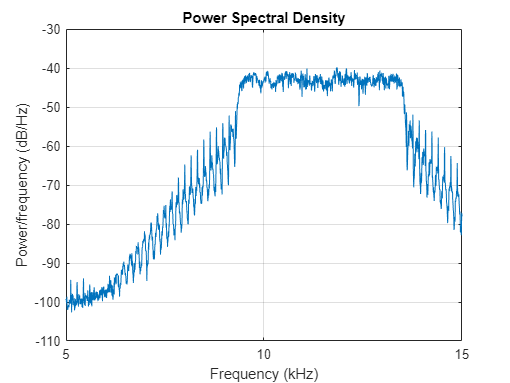

figure; 
title('Frequency domain representation - Broadband signal');
window = hamming(floor(length(signal)/10));
pwelch(real(signal),window,[],[],44100,'centered');
xlim([5 15]);

## 2. Baseband Signal Generation Example

The function is called by simple_tx.m.

%{
% load the parameters of the wave form
pset = pset_load('parameter_sets.csv',1)
% generate the waveform
bband_fs = 20000; % Sampling frequency (Hz)
[bband, pkt, state] = tx(pset, bband_fs);
figure;
plot(real(bband));
title('Time domain representation');
figure; 
title('Frequency domain representation - Baseband signal');
window = hamming(floor(length(bband)/10));
pwelch(bband,window,[],[],20000,'centered');
xlim([-3 3]);
%}

## 3. Simple Receiver Example

This shows calling the full receiver implementation.

It reads parameters from the file 'parameter_sets.csv', which is a spreadsheet. The 2nd parameter selects the set of parameters with #Id 1.

The carrier frequency is 11,520 Hz.

The output is written to file "janus.wav", in the current directory.

% set the verbose mode
global verbose;
verbose = 1;
[rx_pkt, rx_state] = simple_rx('parameter_sets.csv', 1,'stream_driver_args', 'test_janus.wav')

rx_pkt = struct with fields:
            bytes: [54 17 1 180 3 255 255 50]
          version: 3
         mobility: 0
         schedule: 1
            tx_rx: 1
          forward: 0
         class_id: 17
    class_id_name: 'OPEN'
    reserv_repeat: 0
      reserv_time: 107.9157
         app_type: 0
       cargo_size: 0
         app_data: '003FFFF'
              crc: 50
     crc_validity: 1
            cargo: ''


rx_state = struct with fields:
          pset_id: 1
        pset_name: 'Initial JANUS band (9-14 kHz)'
            cfreq: 11520
           bwidth: 3840
         chip_frq: 160
         chip_dur: 0.0063
           prim_q: 13
           prim_a: 2
           nblock: 12
          pkt_idx: 2326
          crg_idx: 0
     pkt_raw_bits: [144×1 double]
     pkt_dec_bits: [64×1 double]
     crg_raw_bits: [80×1 double]
     crg_dec_bits: [32×1 double]
            after: 0.0313
            gamma: 1.0000
            speed: -0.0039
    process_up_to: 2.0112
          ctr_idx: 12250
         bit_prob: [144×1 double]


% rx_payload_ascii = char(rx_pkt.payload)

## Convert from bitstring to signed int

function signedInt = toSignedInt(bitstring)
    signedInt = 0
    value = 1
    for i = 8:-1:1
        if char(extract(bitstring, i)) == '1'
            signedInt = signedInt + value
        end
        value = value * 2
    end
    if char(extract(bitstring, 1)) == '1'
        signedInt = signedInt - 256
    end
end


## Convert from byte object to string

function bitstring = toString(byte)
    if byte < 0
       bitstring = '1';
       byte = byte + 128
    else
        bitstring = '0';
    end

    for i = 6:-1:0
        if (byte - (2^i)) < 0
            bitstring = strcat(bitstring, '0');
        else
            bitstring = strcat(bitstring, '1');
            byte = byte - (2^i);
        end
    end

end